# Construction of New Gait Library (MTA3)

The following MATLAB Live Script builds a a new gait library for the three-limbed MTA soft robot. The first three gaits are translation gaits and the last three gaits are rotation gaits. Each gait is tested for two trials with 60 cycles each. The first trial orients the robot at 0 degrees (yellow marker on the limb pointed to the left) with the tether on the left (denoted "L"). The second trial orients the robot at 180 degrees (yellow marker on the limb pointed to the right) with the tether on the left (denoted "Lf" for "left flipped). No connections/wires or control sequences are changed between the two trials. The two trials are used both to analyze the variance and to reduce any effects / biases caused by the tether positioning or any imperefctions / tilting on the ground.

% Dependencies:
%   +demos/data/visualtracking
%   +offlineanalysis/GaitTest
%   +gaitdef/Gait

% [0] == Script setup
clear; clc; close all

% Add dependencies to classpath
cd 'D:\clfreeman7\Documents\GitHub\IROS2022\demos';
addpath('../');
addpath('data/visualtracking');


% Configure figure tex interpreters
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(0, 'DefaultAxesFontSize', 18);

% Decide which figures to show.
show_markers = false;             % Labels the markers on the robot to determine marker order for data alignment.
show_gait_sequences = false;      % Visualizes the discrete robot configurations in each gait sequence.

## Extract and define parameters for GaitTest() objects.

#### From Black Mat (20230127/20230129) Experiments:

% Writing the gait names.
mat_T = 'ABC';    % Translation gaits on the black mat.
mat_R = 'DEF';      % Rotation gaits on the black mat.
ad_hoc = 'GHI';
names_bm = [mat_T mat_R ad_hoc];

% Defining the experiment data file location.
exp_location{1} = 'data/visualtracking/MTA3/Black_Mat/';

for i = 1:9
    % (L): Robot marker pointed to left, tether on left.
    vid_name = ['3',names_bm(i),'_60_L'];
    gait_names{2*i-1} = [vid_name,'.mat'];

    % (Lf): Robot marker pointed to right, tether on left ("left flipped").
    vid_name = ['3',names_bm(i),'_60_Lf'];
    gait_names{2*i} = [vid_name,'.mat'];
end

#### From Whiteboard (20230127/20230129) Experiments:

% Writing the gait names.
whiteboard_T = 'JKL';    % Translation gaits on the black mat.
whiteboard_R = 'MNO';      % Rotation gaits on the black mat.
names_wb = [whiteboard_T whiteboard_R mat_T(1) mat_R(1) ad_hoc];

% Defining the experiment data file location.
exp_location{2} = 'data/visualtracking/MTA3/Whiteboard/';

for i = 1:8
    % (L): Robot marker pointed to left, tether on left.
    vid_name = ['3',names_wb(i),'_60_L'];
    gait_names{end+1} = [vid_name,'.mat'];
end

for i = 9:11
    % (L): Robot marker pointed to left, tether on left.
    vid_name = ['3',names_wb(i),'_60_L'];
    gait_names{end+1} = [vid_name,'.mat'];

    % (Lf): Robot marker pointed to right, tether on left ("left flipped").
    vid_name = ['3',names_wb(i),'_60_Lf'];
    gait_names{end+1} = [vid_name,'.mat'];
end

#### From Carpet (20230201) Experiments:

% Writing the gait names.
carpet_T = 'QRS';    % Translation gaits on the black mat.
carpet_R = 'TUV';      % Rotation gaits on the black mat.
names_ct = [carpet_T carpet_R mat_T(1) mat_R(1) ad_hoc];

% Defining the experiment data file location.
exp_location{3} = 'data/visualtracking/MTA3/Carpet/';

for i = 1:11
    % (L): Robot marker pointed to left, tether on left.
    vid_name = ['3',names_ct(i),'_60_L'];
    gait_names{end+1} = [vid_name,'.mat'];
end


### Build Experiment Matrix

if isrow(gait_names)
    gait_names = gait_names';
end
n_gaits = length(gait_names);

% Extract characteristics of each gait test.
file_names = split(gait_names, '.');
gait_characteristics = cell(n_gaits, 7);
for i = 1:n_gaits
    gait_characteristics(i, 1) = num2cell(i);
    n_underscores = count(gait_names{i}, '_');
    if n_underscores == 2
        gait_characteristics(i, [2,3,6]) = split(file_names(i,1), '_');
        gait_characteristics(i, 4) = cellstr('NS');
        gait_characteristics(i, 5) = cellstr('NF');
        if ismember(i,1:18)
            gait_characteristics(i, 7) = cellstr('Black Mat');
        elseif ismember(i,19:32)
            gait_characteristics(i, 7) = cellstr('Whiteboard');
        else 
            gait_characteristics(i, 7) = cellstr('Carpet');
        end
    else
        gait_characteristics(i, 2:7) = split(file_names(i,1), '_');
    end
end
characteristics = ["Experiment", "Gait", "#Cycles", "Tether", ...
              "Protocol", "Placement", "Surface"];
% Build table.
experiments = cell2table(gait_characteristics, "VariableNames", ...
              characteristics);
sorted_exps = sortrows(experiments, characteristics([2, 4, 5, 6, 7]))

sorted_exps = 43×7 table
    Experiment     Gait     #Cycles    Tether    Protocol    Placement       Surface    
    __________    ______    _______    ______    ________    _________    ______________

         1        {'3A'}    {'60'}     {'NS'}     {'NF'}      {'L' }      {'Black Mat' }
        39        {'3A'}    {'60'}     {'NS'}     {'NF'}      {'L' }      {'Carpet'    }
        25        {'3A'}    {'60'}     {'NS'}     {'NF'}      {'L' }      {'Whiteboard'}
         2        {'3A'}    {'60'}     {'NS'}     {'NF'}      {'Lf'}      {'Black Mat' }
         3        {'3B'}    {'60'}     {'NS'}     {'NF'}      {'L' }      {'Black Mat' }
         4        {'3B'}    {'60'}     {'NS'}     {'NF'}      {'Lf'}      {'Black Mat' }
         5        {'3C'}

% Construct titles. 
title_components = string(gait_characteristics);
title_components(strcmp(experiments.Protocol, 'F'), 5) = 'following';
title_components(strcmp(experiments.Protocol, 'NF'), 5) = 'not following';
title_components(strcmp(experiments.Placement, 'L'), 6) = 'left';
title_components(strcmp(experiments.Placement, 'Lf'), 6) = 'left (flipped)';
title_components = [repmat(["Experiment" ":" "cycles of Gait" "with" "tether (" "," ")," "on"], n_gaits, 1) title_components];
title_matrix = title_components(:, [1,9,2,11,3,10,4,12,5,14,6,13,7,8,15]);
exp_title = join(title_matrix);
% Define experimental parameters after investigating videos. 
frame_start_list(1:2:18) = [130,107,103,115,81,124,111,109,108];     % Black Mat L
frame_start_list(2:2:18) = [98,105,121,130,82,106,115,121,124];      % Black Mat Lf

frame_start_list(19:26) = [38,35,34,33,52,30,34,30];      % Whiteboard L (not ad-hoc)
frame_start_list(27:32) = [117,124,118,106,101,123];      % Whiteboard ad-hoc (L and Lf)

frame_start_list(33:43) = [153,142,150,146,153,138,144,146,168,148,151];     % Black Mat L

% Find marker order by investigating first frame.
marker_order_list = repmat([1 3 5 6 4 2],n_gaits, 1);
marker_order_list([3,9,11,17,21,22,23,25,27,31,41,42],:) = repmat([1 2 4 6 5 3],12,1);
marker_order_list([24,29,34],:) = repmat([1 2 5 6 4 3],3,1);

marker_order_list([5,36,39,40],:) = repmat([2 1 4 6 5 3],4,1);
marker_order_list(15,:) = [2 3 5 6 4 1];

marker_order_list(4,:) = [5 4 2 1 3 6];
marker_order_list(18,:) = [5 6 3 1 2 4];

marker_order_list([2,10,12,16,30,32],:) = repmat([6 4 2 1 3 5],6,1);
marker_order_list([6,8,28],:) = repmat([6 5 2 1 3 4],3,1);
marker_order_list(14,:) = [6 5 3 1 2 4];




% Initialize the stability experiment struct. 
MTA3 = struct('params', [], 'raw_data', []);
gait_sequences = cell(n_gaits,1);
j = 1;

% Extract data.
for i = 1:n_gaits
    % Define robot / experiment parameters.
    MTA3(i).params.robot_name = 'MTA3';
    if ismember(i,1:18)
        MTA3(i).params.substrate = 'black mat';
        filename = [exp_location{1} gait_names{i}];
    elseif ismember(i,19:32)
        MTA3(i).params.substrate = 'whiteboard';
        filename = [exp_location{2} gait_names{i}];
    else
        MTA3(i).params.substrate = 'carpet'; 
        filename = [exp_location{3} gait_names{i}];
    end
    MTA3(i).params.n_markers = 6;
    MTA3(i).params.n_unique_states = 8;
    MTA3(i).params.transition_time = .55;
    MTA3(i).params.pixel_length = 1/8.6343;     % cm per pixel
    if ismember(i,18:26)
        MTA3(i).params.pixel_length = MTA3(i).params.pixel_length/480*1080;     
    end

    % Define number of gait cycles run.
    MTA3(i).params.n_cycles= str2double(gait_characteristics{i,3}); 
         % accounts for pause after first cycle in some of the videos

    % Extract and store first frame information.
    MTA3(i).params.frame_1 = frame_start_list(i);
    MTA3(i).params.marker_order = marker_order_list(i,:);

    MTA3(i).raw_data = load(filename).tracking_data;  
    switch experiments.Gait{i}(2)
        case "A"
            gait_sequences{i} = [6,3];
        case "B"
            gait_sequences{i} = [8,2,1];
        case "C"
            gait_sequences{i} = [6,4,5,7,1];
        case "D"
            gait_sequences{i} = [4,2,1];
        case "E"
            gait_sequences{i} = [3,4,2,6,7,1];
        case "F"
            gait_sequences{i} = [7,5,6,4,2,1];
        case "G"
            gait_sequences{i} = [1,8];
        case "H"
            gait_sequences{i} = [2,3,5];
        case "I"
            gait_sequences{i} = [5,8,4,1];
        case "J"
            gait_sequences{i} = [6,4,5,2]; 
        case "K"
            gait_sequences{i} = [4,7,5,1];
        case "L"
            gait_sequences{i} = [5,3];
        case "M"
            gait_sequences{i} = [5,1];
        case "N"
            gait_sequences{i} = [1,4,2,6];
        case "O"
            gait_sequences{i} = [5,7,6,2];
        case "Q"
            gait_sequences{i} = [7,3];
        case "R"
            gait_sequences{i} = [7,4,3];
        case "S"
            gait_sequences{i} = [4,5,3,2];
        case "T"
            gait_sequences{i} = [2,6,5,3,8,4];
        case "U"
            gait_sequences{i} = [3,8,7,6,4,5,2];
        case "V"
            gait_sequences{i} = [7,4,2,6,5,3,1];
    end
end

## Analyze the experiment data:

#### 1. Rotate the data w.r.t. the initial global orientation.

% Define first experiment first frame orientation as theta = 0. 
markers_x(1, :) = MTA3(1).raw_data(1, 1:3:MTA3(1).params.n_markers*3-2);
markers_y(1, :) = MTA3(1).raw_data(1, 2:3:MTA3(1).params.n_markers*3-1);
centroid(:, :, 1) = mean([markers_x(1, :); markers_y(1, :)], 2);
% Move initial position to (0,0) origin.
reference_markers = [markers_x(1, marker_order_list(1,:)); markers_y(1, marker_order_list(1,:));]...
                    - centroid(:, :, 1);
% For each trial, rotate data to align first frame global orientations.
 for i = 1:n_gaits
    % Find initial rotation matrix for each trial to have consistent fixed frame.
    markers_x(i, :) = MTA3(i).raw_data(1, 1:3:MTA3(i).params.n_markers*3-2);
    markers_y(i, :) = MTA3(i).raw_data(1, 2:3:MTA3(i).params.n_markers*3-1);
    centroid(:, :, i) = mean([markers_x(i, :); markers_y(i, :)], 2);

    % Move initial position to (0,0) origin.
    shifted_markers = [markers_x(i, MTA3(i).params.marker_order);
                       markers_y(i, MTA3(i).params.marker_order)]...
                       - centroid(:, :, i);

    % Find orientation of subsequent trials w.r.t. first trial GCS.
    [regParams,~,~] = absor(reference_markers, shifted_markers);
    MTA3(i).params.R_1 = [regParams.R zeros(2,1); 0 0 1];
 end


#### 2. Instantiate GaitTest() objects for each experimental trial.

 %This analyzes the data from each trial to find motion primitive twist information.
% Instantiate objects for each gait tested. 
all_gaits = offlineanalysis.GaitTest.empty(0,n_gaits); 
gait_defs = gaitdef.Gait.empty(0,n_gaits);
tail_idx = cell(n_gaits, 1);
head_idx = cell(n_gaits, 1);
delta_poses = cell(n_gaits,1);
global_theta = cell(n_gaits,1);
twists = cell(n_gaits,1);
cent_rot = cell(n_gaits,1);
rad_curv = cell(n_gaits,1);
orientation = cell(n_gaits,1);
global_change = cell(n_gaits,1);
total_dist = cell(n_gaits,1);

#### 3. Calculate twists for each gait experiment.

% Calculate twists for each gait experiment.
for i = 1:n_gaits
    all_gaits(i) = offlineanalysis.GaitTest(MTA3(i).raw_data, ...
                                                 gait_sequences{i}(1,:), ...
                                                 MTA3(i).params);
    gait_defs(i) = gaitdef.Gait(all_gaits(i), MTA3(i).params);
    % Manually find the twists. 
    % Extract gait / experiment details. 
    n_cycles = all_gaits(i).n_cycles;
    len_gait = all_gaits(i).len_gait;
     for j = 1:n_cycles
         % Record indexes for each gait tail and head. 
         tail_idx{i}(1,j) = all_gaits(i).keyframes(len_gait*(j-1)+2);
         head_idx{i}(1,j) = all_gaits(i).keyframes(len_gait*j+2);

         % Find change in poses w.r.t. global inertial frame for each gait. 
         delta_poses{i}(:,j) = all_gaits(i).poses(:, head_idx{i}(1,j)) - all_gaits(i).poses(:, tail_idx{i}(1,j));
         %delta_poses{i}(1:2,j) = all_gaits(i).pixel_length*delta_poses{i}(1:2,j);

         % Find global orientation of robot at each gait tail. 
         global_theta{i}(:,j) = all_gaits(i).poses(3, tail_idx{i}(1,j));

         % Convert from global frame to body frame.  
         rot_mat =  [cos(global_theta{i}(1,j)) -sin(global_theta{i}(1,j)); sin(global_theta{i}(1,j)) cos(global_theta{i}(1,j))];
         delta_poses{i}(1:2,j) = rot_mat'*delta_poses{i}(1:2,j);
         R =  [cos(delta_poses{i}(3,j)) -sin(delta_poses{i}(3,j)); sin(delta_poses{i}(3,j)) cos(delta_poses{i}(3,j))];
         % Convert to twists.
         twists{i}(:,j)  = gait_defs(i).delta_pose_2_twist(delta_poses{i}(:,j), all_gaits(i).transition_time*len_gait);

         % Find instantaneous center of rotation.
         cent_rot{i}(:,j) = (eye(2) - R)\delta_poses{i}(1:2, j);

         % Find instantaneous radius of curvature.
         rad_curv{i}(1,j) = norm(cent_rot{i}(:,j));
     end
     %orientation{i} = cumsum(rad2deg(reshape(all_gaits(i).delta_theta',1,[])));
     %global_change{i} = all_gaits(i).poses(:,all_gaits(i).keyframes(3:end)) - ...
    %     all_gaits(i).poses(:,all_gaits(i).keyframes(2:end-1));
     %total_dist{i} = (global_change{i}(1,:).^2+(global_change{i}(2,:).^2)).^2;
     lin_vel{i} = (twists{i}(1,:).^2+twists{i}(2,:).^2).^.5;
     avg_lin_speed(1,i) = mean(lin_vel{i});
     err_lin_speed(1,i) = var(lin_vel{i}).^.5;
     avg_rot_speed(1,i) = abs(rad2deg(mean(twists{i}(3,:))));
     err_rot_speed(1,i) = rad2deg(var(twists{i}(3,:)).^.5);
end
speed_data = [avg_lin_speed; err_lin_speed; avg_rot_speed; err_rot_speed];

## Plot the gait characteristics.

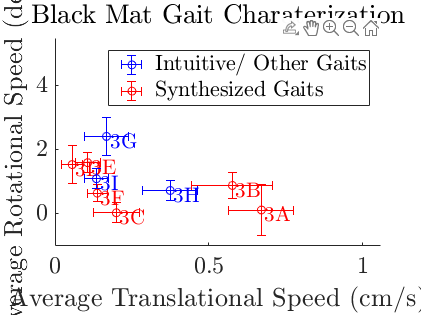

figure
hold on
plot_gait_char(1:2:11,names_bm(1:6),speed_data,1)
plot_gait_char(13:2:17,names_bm(7:9),speed_data,0)
ylim([-1 5.5])
xlim([0 1.06])
title('Black Mat Gait Charaterization', 'FontSize',20)
ax = gca;
legend([ax.Children(4), ax.Children(11)],["Intuitive/ Other Gaits", "Synthesized Gaits"],'Interpreter','latex')

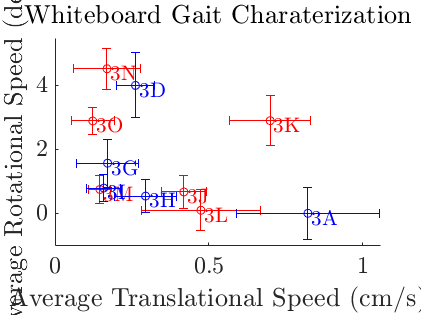


figure
hold on
plot_gait_char(19:24,names_wb(1:6),speed_data,1)
plot_gait_char([25:27,29,31],names_wb(7:11),speed_data,0)
title('Whiteboard Gait Charaterization','FontSize',20)
ylim([-1 5.5])
xlim([0 1.06])

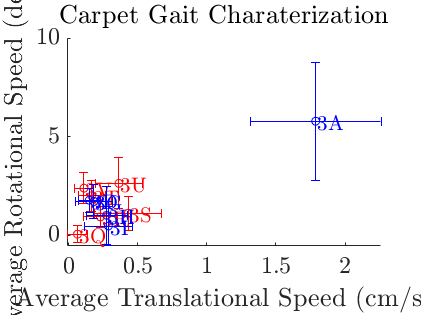


figure
hold on
plot_gait_char(33:38,names_ct(1:6),speed_data,1)
plot_gait_char(39:43,names_ct(7:11),speed_data,0)

title('Carpet Gait Charaterization', 'FontSize',20)

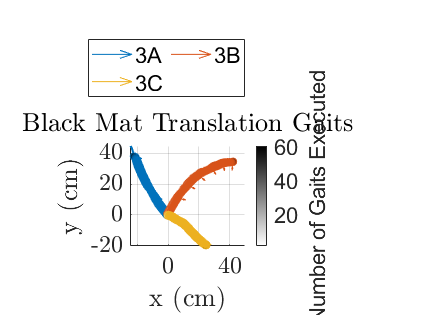



trial_labels  = ["3A","3B","3C"];
figure
plot_trajs(all_gaits, [1,3,5], trial_labels, 5)
title("Black Mat Translation Gaits")

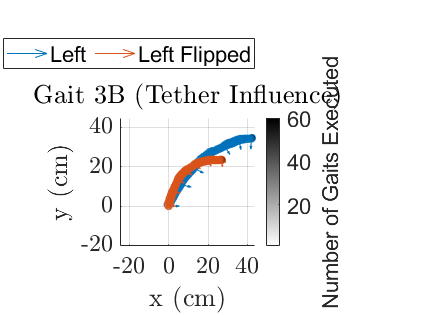

xl_bm = xlim;
yl_bm = ylim;

trial_labels = ["Left","Left Flipped"];
figure
plot_trajs(all_gaits, [3,4], trial_labels, 5)
title("Gait 3B (Tether Influence)")
ylim(yl_bm)
xlim(xl_bm)

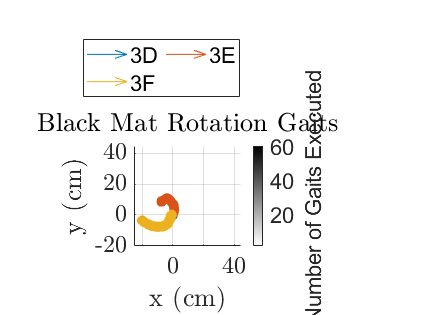



trial_labels  = ["3D","3E","3F"];
figure
plot_trajs(all_gaits, [7,9,11], trial_labels, 5)
title("Black Mat Rotation Gaits")
ylim(yl_bm)
xlim(xl_bm)

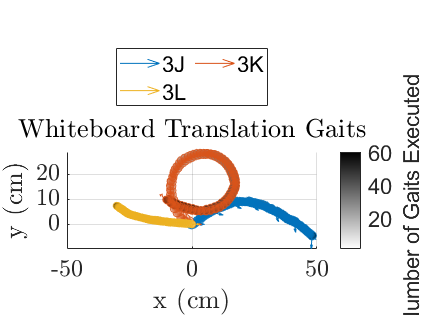


trial_labels  = ["3J","3K","3L"];
figure
plot_trajs(all_gaits, 19:21, trial_labels, 5)
title("Whiteboard Translation Gaits")

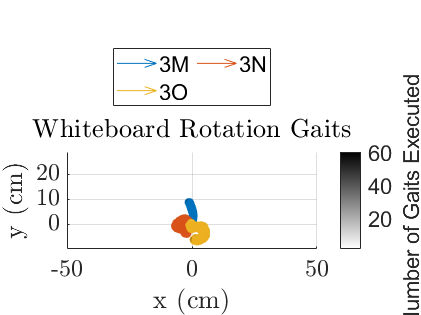

xl_wb = xlim;
yl_wb = ylim;

figure
trial_labels  = ["3M","3N","3O"];
plot_trajs(all_gaits, 22:24, trial_labels, 5)
title("Whiteboard Rotation Gaits")
xlim(xl_wb)
ylim(yl_wb)

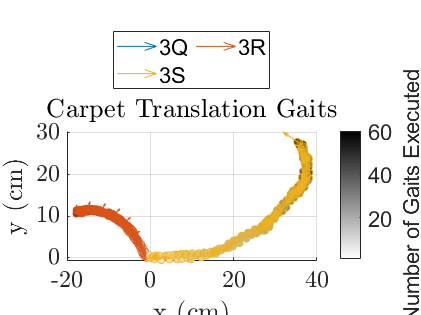


figure
trial_labels  = ["3Q","3R","3S"];
plot_trajs(all_gaits, 33:35, trial_labels, 5)
title("Carpet Translation Gaits")

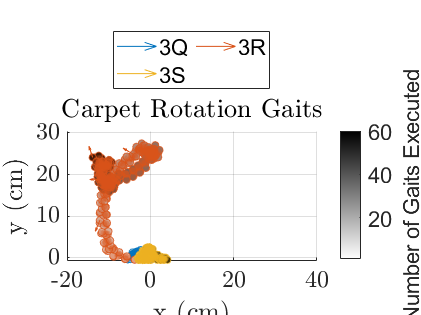

xl_ct = xlim;
yl_ct = ylim;

figure
trial_labels  = ["3Q","3R","3S"];
plot_trajs(all_gaits, 36:38, trial_labels, 5)
title("Carpet Rotation Gaits")
xl_wb = xlim;
yl_wb = ylim;
xlim(xl_ct)
ylim(yl_ct)

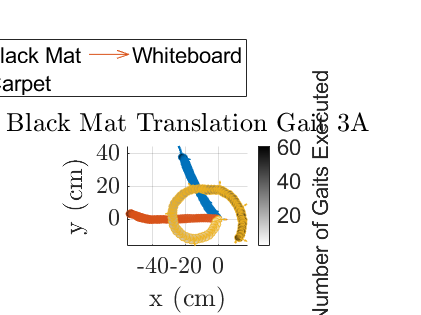


figure
trial_labels  = ["Black Mat","Whiteboard","Carpet"];
plot_trajs(all_gaits, [1,25,39], trial_labels, 5)
title("Black Mat Translation Gait 3A")

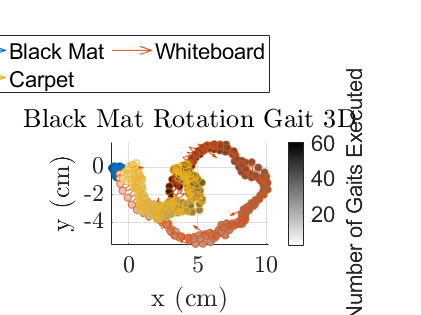


figure
plot_trajs(all_gaits, [7,26,40], trial_labels, 5)
title("Black Mat Rotation Gait 3D")

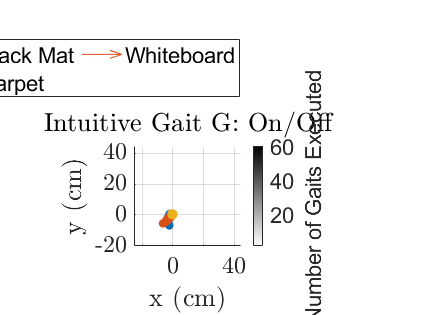


figure
plot_trajs(all_gaits, [13,27,41], trial_labels, 5)
title("Intuitive Gait G: On/Off")
xlim(xl_bm)
ylim(yl_bm)

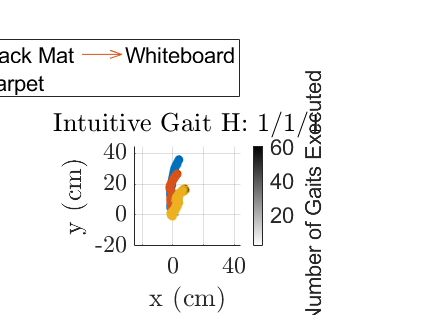


figure
plot_trajs(all_gaits, [15,29,42], trial_labels, 10)
title("Intuitive Gait H: 1/1/1")
xlim(xl_bm)
ylim(yl_bm)

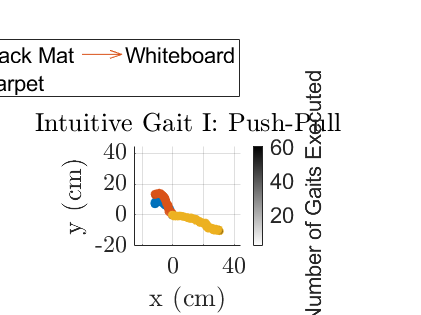


figure
plot_trajs(all_gaits, [17,31,43], trial_labels, 10)
title("Intuitive Gait I: Push-Pull")
xlim(xl_bm)
ylim(yl_bm)

## Construct comparative ICR / ROC plots.

## Make gait libraries.

## Show first frame of experiments to determine marker order.

if show_markers
    figure
    %tiledlayout(5,6)
    tiledlayout(3,4)
    for i = 33:43
    pic_name = gait_names{i};
    pic_name(end-3:end) = [];
    % Plot first image of experiment video.
    file_name = ['data/visualtracking/MTA3/Carpet/firstframe_', pic_name, '.jpg'];
    pic = imread(file_name);
    nexttile;
    imshow(pic)
    title("Trial " + i)
    hold on
    
    % Plot labeled (i.e., numbered) markers on top of image.
    markers_x(i, :) = MTA3(i).raw_data(1, 1:3:MTA3(i).params.n_markers*3-2);
    markers_y(i, :) = MTA3(i).raw_data(1, 2:3:MTA3(i).params.n_markers*3-1);
%     if iTrial ~=5
    for m = 1:MTA3(i).params.n_markers
            text(markers_x(i, m), 1080-markers_y(i, m), num2str(m),'Color','white','FontSize',14);
%     end
    end
    
    % Adjust size.
    if ismember(i,19:26)
        xlim([min(markers_x(i, :))-90, max(markers_x(i, :))+90]);
        ylim([min(1080 - markers_y(i, :))-90, max(1080 - markers_y(i, :))+90]);
    else
        xlim([min(markers_x(i, :))-200, max(markers_x(i, :))+200]);
        ylim([min(1080 - markers_y(i, :)) - 200, max(1080 - markers_y(i, :))+200]);
    end
    end
    
end

## Show graphical representations of gait sequences.

if show_gait_sequences
    %I = imread('MTA3_Black_Mat.jpg');
    figure
    n_limbs = log2(all_gaits(1).n_unique_states);    % number of robot limbs
    state_map = dec2bin(0:all_gaits(1).n_unique_states-1);
    T = tiledlayout(7,3);
    T.TileSpacing = 'compact';
    T.Padding = 'compact';
    gait_order = char(experiments.Gait);
    [~,gait_idx,~] = unique(gait_order(:,2),'stable');
    %gait_idx = sort(gait_idx);
    % Make adjacency matrix for the graphs. 
    adj_mat = zeros(n_limbs+1);
    adj_mat(2:end,1) = ones(n_limbs, 1);
    adj_mat(1,2:end) = ones(1, n_limbs);

    for i = 1:15 %21
        nexttile(T,i);
        % String of robot states for a given gait.
        states = gait_sequences{gait_idx(i)};
        len_gait = length(states);
        seq = join(string(states));
        rep_adj_mat = repmat({adj_mat},1,len_gait);
        Adj_Mat = blkdiag(rep_adj_mat{:});
        n_nodes = length(Adj_Mat);
        G = graph(Adj_Mat);
        h = plot(G,'k:.','LineWidth',1.5);
        n_edges = len_gait*n_limbs;
        edge_logic = str2num(reshape(transpose(state_map(states,:)),n_edges,1));
        n_act = nnz(edge_logic);
        
        off_idx = find(~edge_logic);
        G_act = G;
        G_act = rmedge(G_act,off_idx);
        highlight(h,G_act,'EdgeColor','r','LineWidth',3,'LineStyle','-')

        XData = [0 .5 -1 .5];
        for j = 1:len_gait-1
           XData = [XData (XData(end-3:end)+2.5)];
        end
        h.XData = XData;
        h.YData = repmat([0 -sqrt(3)/2 0 sqrt(3)/2],1,len_gait);
        h.ZData = zeros(1,n_nodes);
        node_labels = repmat({''},1,n_nodes);
        node_labels(2:n_limbs+1) = {'a', 'b', 'c'};
        labelnode(h,1:n_nodes,node_labels);
        axis equal
        xlim([-inf inf]) 
        ylim([-1.5 1.5])
        axis off
        title("Gait "+experiments.Gait(gait_idx(i))+": ["+seq +"]", 'FontSize',14)
    end
   states_new = {[7,3];[7,4,3];[4,5,3,2];[2,6,5,3,8,4];[3,8,7,6,4,5,2]; [7,4,2,6,5,3,1]};
         names_new = {'3Q';'3R';'3S';'3T';'3U';'3V'}; 
   for i = 16:21

       nexttile(T,i);
        % String of robot states for a given gait.
        states = states_new{i-15};
        len_gait = length(states);
        seq = join(string(states));
        rep_adj_mat = repmat({adj_mat},1,len_gait);
        Adj_Mat = blkdiag(rep_adj_mat{:});
        n_nodes = length(Adj_Mat);
        G = graph(Adj_Mat);
        h = plot(G,'k:.','LineWidth',1.5);
        n_edges = len_gait*n_limbs;
        edge_logic = str2num(reshape(transpose(state_map(states,:)),n_edges,1));
        n_act = nnz(edge_logic);
        
        off_idx = find(~edge_logic);
        G_act = G;
        G_act = rmedge(G_act,off_idx);
        highlight(h,G_act,'EdgeColor','r','LineWidth',3,'LineStyle','-')

        XData = [0 .5 -1 .5];
        for j = 1:len_gait-1
           XData = [XData (XData(end-3:end)+2.5)];
        end
        h.XData = XData;
        h.YData = repmat([0 -sqrt(3)/2 0 sqrt(3)/2],1,len_gait);
        h.ZData = zeros(1,n_nodes);
        node_labels = repmat({''},1,n_nodes);
        node_labels(2:n_limbs+1) = {'a', 'b', 'c'};
        labelnode(h,1:n_nodes,node_labels);
        axis equal
        xlim([-inf inf]) 
        ylim([-1.5 1.5])
        axis off
        title("Gait "+names_new(i-15)+": ["+seq +"]", 'FontSize',14)

    end
end

function plot_gait_char(trial_nums, trial_labels, speed_data, is_synth)
if is_synth
    l_color = "red";
else
    l_color = "blue";
    xlabel('Average Translational Speed (cm/s)')
    ylabel('Average Rotational Speed (deg/s)')
end
x = speed_data(1,trial_nums);
    x_err = speed_data(2,trial_nums);
    y = speed_data(3,trial_nums);
    y_err = speed_data(4,trial_nums);
    
    errorbar(x,y,y_err,y_err,x_err,x_err,"o","Color",l_color); 
for i = 1:length(trial_nums)
    text(x(i)+.01, y(i)-.2, "3"+trial_labels(i),"Color", l_color,'FontSize',16)
end
end


function plot_trajs(all_gaits, trial_nums, trial_labels, marker_size, n_cycles, color_array)
if nargin<5
    n_cycles = [];
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE"];
end
if nargin<6
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE"];
end
k = 1;
lgd_idxs = [];
for i = trial_nums
    if isempty(n_cycles)
        all_gaits(i).plot;
    else
        all_gaits(i).plot(n_cycles);
    end
    ax = gca;
    if isprop(ax.Children(1), "Color")
        ax.Children(1).Color = color_array(k);
    else
       % ax.Children(1).CData = color_array(k);
    end
    ax.Children(2).MarkerEdgeColor = "none";
    ax.Children(2).MarkerFaceColor = color_array(k); 
    ax.Children(2).MarkerFaceAlpha = .3;
    ax.Children(2).MarkerFaceAlpha = .3;
    ax.Children(3).MarkerEdgeColor = color_array(k);
    ax.Children(3).MarkerEdgeAlpha = .8;
    if isprop(ax.Children(4), "Color")
        ax.Children(4).Color = color_array(k);
    else
        %ax.Children(4).CData = color_array(k);
    end
    k = k+1;
    lgd_idxs = [lgd_idxs ax.Children(1)];
end
colormap(flip(gray))
a = colorbar;
a.Location = "eastoutside";
a.Label.String = 'Number of Gaits Executed';
lgd = legend(lgd_idxs, trial_labels);
lgd.Location = "northoutside";
lgd.Orientation = "horizontal";
if length(trial_nums)>2
    lgd.NumColumns = 2;
end
end

function twists_plot = plot_twists(twists, global_theta, trial_nums, trial_labels, ylims)
    figure;
    twists_plot = tiledlayout(3,2);
    ylabels = {'$v_x$ (cm/s)', '$v_y$ (cm/s)', '$\omega$ (deg/s)'};

    % Plot twist components vs number of gait cycles.
    for i = 1:3
        nexttile(2*i - 1);
        hold on;
        for j = 1:length(trial_nums)        
            plot(twists{trial_nums(j)}(i,:))
        end
        ylabel(ylabels{i}, 'FontSize',14)
        if ~isempty(ylims)
            ylim(ylims(i,:))
        end
    end
    xlabel('Number of Gait Cycles', 'FontSize',14)
    
    % Plot twist components vs global robot orientation.
    for i = 1:3
        nexttile(2*i);
        hold on;
        for j = 1:length(trial_nums)        
            scatter(rad2deg(global_theta{trial_nums(j)}(1,:)),twists{trial_nums(j)}(i,:))
        end
        xlim([-180 180])
        ylabel(ylabels{i}, 'FontSize',14)
        if ~isempty(ylims)
            ylim(ylims(3+i,:))
        end
    end
    xlabel('Global robot orientation $\theta_G$ (deg)', 'FontSize',14)

    if length(trial_labels) > 1
        lgd = legend(trial_labels, 'FontSize',18);
        lgd.Orientation = 'horizontal';
        lgd.Layout.Tile = 'north';
    else
        plot_title = ['Twist (body velocity) for', trial_labels];
        title(twists_plot,plot_title, 'FontSize',22) 
    end
end

function plot_ICR(cent_rot, rad_curv, trial_nums, trial_labels, ylims)
figure
tiledlayout(2,1)
for i = trial_nums
    nexttile(1)
    hold on;
    scatter(cent_rot{i}(1,:), cent_rot{i}(2,:),'*')
    nexttile(2)
    hold on;
    plot(1:length(rad_curv{i}(1,:)), rad_curv{i}(1,:))
end
nexttile(1)
title('Instantaneous center of rotation IC')
xlabel('x (cm)')
if ~isempty(ylims)
    ylim(ylims(1,:))
end
ylabel('y (cm)')
daspect([1 1 1]);
nexttile(2)
if ~isempty(ylims)
    ylim(ylims(2,:))
end
lgd = legend(trial_labels, 'Orientation', 'Horizontal');
lgd.Layout.Tile = 'north';

title('Radius of curvature')
xlabel('Number of Gait Cycles')
ylabel('$\| IC\|  (cm)$')
end